# **Eigenvalue solution:**    3-dof Spring Mass Damper system

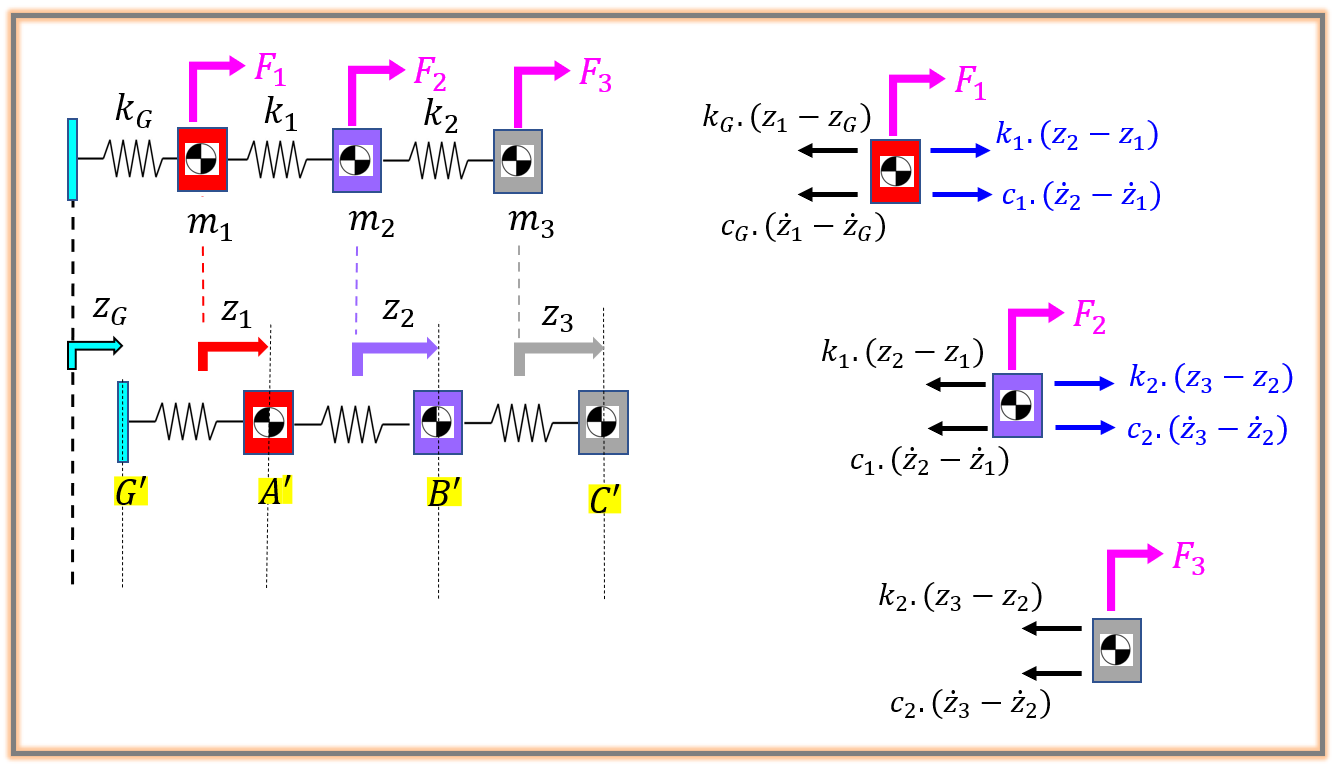

Recall the **UNdamped** homogeneous system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

And let's look for a harmonic solution of the form:

- 
$$X\left(t\right)=\;\;\;\;\;\;v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{X} \left(t\right)=\;\;\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp X\left(t\right)$$


- 
$$\ddot{X} \left(t\right)=\;\;\;-1\ldotp \omega^2 \ldotp X\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(t\right)\;=\;0$$


- 
$$K\ldotp X\left(t\right)=M\ldotp X\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp X\left(t\right)=\omega^2 \ldotp X\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

Outputs:

- `w2_list   :`     a vector of the eigenvalues, i.e.:    $\omega^2$ 

- `eVec_PHI  :   `a matrix of the nomalized eigenvectors i.e.:   $I\;\;={\;\;V}^T \ldotp M\ldotp V$    and     $\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$

function [w2_list, eVec_PHI] = bh_newton_smd_3dof_eig( m1,m2,m3,  kg,k1,k2 )

   [M_mat, ~, K_mat, ~] = bh_newton_smd_3dof_model_MCK( m1,m2,m3, kg,k1,k2,  "DAMPING_C",  [0,0,0] );

   [V_mat, w_col, w_table] = bh_do_modal_analysis( M_mat, K_mat);

   % take care of OUTPUTS

   % NOTE: we are returning a column array of OMEGA^2
   w2_list     =  w_col.^2;
   eVec_PHI    =  V_mat;
end